clear

# India-Pakistan Arms Race Richardson Model

### Data Preprocessing

First we will import the data from Expenditure.csv and ExpenditurePercent.csv into separate tables. These csv files can be found at:

- Absolute spending: [https://data.worldbank.org/indicator/MS.MIL.XPND.CD](https://data.worldbank.org/indicator/MS.MIL.XPND.CD)

- Percent of GDP: [https://data.worldbank.org/indicator/MS.MIL.XPND.GD.ZS](https://data.worldbank.org/indicator/MS.MIL.XPND.GD.ZS) 

We will extract from each of these tables the countries that have military expenditure data available from 1960-2020 with no missing values.

dataLines = [5, Inf];
timeline = 1960:2020;
yearNames = string(timeline);

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 65, "Encoding", "UTF-8");

% Specify range and delimiter
opts.DataLines = dataLines;
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["CountryName", "CountryCode", "IndicatorName", "IndicatorCode", yearNames];
opts.VariableTypes = ["string", "string", "categorical", "categorical", repelem("double",61)];
opts.VariableNamingRule = 'preserve';

% https://data.worldbank.org/indicator/MS.MIL.XPND.CD 
expenseRaw = readtable("Expenditure.csv", opts);

%drop first row & extra cols
expenseRaw(1,:) = [];
expenseRaw(:,[3, 4, end]) = [];

%sort by country name
expenseRaw = sortrows(expenseRaw,"CountryName","ascend");

%divide all doubles by 1e9 to get numbers in billions USD
expenseNum = expenseRaw{:,vartype('numeric')};
expenseNum = expenseNum/1e9;
%index of empty rows
idx = all(isnan(expenseNum),2); %column logical
expenseRaw{:,vartype('numeric')} = expenseNum;

expenseRaw = expenseRaw(~idx,:); %drop all empty rows

%take countries with data for all years
expenseFull = expenseRaw;
expenseNum = expenseFull{:,vartype('numeric')};
%index of all full rows
idx = all(~isnan(expenseNum),2);
expenseFull = expenseFull(idx,:);

%interpolate missing values
%expenseRaw{:,vartype('numeric')} = fillmissing(expenseRaw{:,vartype('numeric')},'pchip',2); 

%% Set up the Import Options and import the data of military expenditure as a % of GDP
opts = delimitedTextImportOptions("NumVariables", 65, "Encoding", "UTF-8");

% Specify range and delimiter
opts.DataLines = dataLines;
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["CountryName", "CountryCode", "IndicatorName", "IndicatorCode", yearNames];
opts.VariableTypes = ["string", "string", "categorical", "categorical", repelem("double",61)];
opts.VariableNamingRule = 'preserve';

percentRaw = readtable("ExpenditurePercent.csv", opts);

%drop first row & extra cols
percentRaw(1,:) = [];
percentRaw(:,[3, 4, end]) = [];

%sort by country name
percentRaw = sortrows(percentRaw,"CountryName","ascend");

%divide all doubles by 100 to get percent on a scale from 0-1
percentNum = percentRaw{:,vartype('numeric')};
percentNum = percentNum/100;
%index of empty rows
idx = all(isnan(percentNum),2); %column logical
percentRaw{:,vartype('numeric')} = percentNum;

percentRaw = percentRaw(~idx,:); %drop all empty rows

%take countries with data for all years
percentFull = percentRaw;
percentNum = percentFull{:,vartype('numeric')};
%index of all full rows
idx = all(~isnan(percentNum),2);
percentFull = percentFull(idx,:);


%percentRaw{:,vartype('numeric')} = fillmissing(percentRaw{:,vartype('numeric')},'pchip',2);


%clear variables that will not be used again
clear opts idx percentNum expenseNum

### Military Spending

Fit data for Inida's and Pakistan's expenditure to the Richardson model.

%extract data for India and find the derivatives of the list 
indiaIdx = expenseFull.CountryName == 'India';
india = expenseFull{indiaIdx, vartype('numeric')};
indiaDer = derivative(india,1,2);

%extract data for Pakistan and find the derivatives of the list 
pakiIdx = expenseFull.CountryName == 'Pakistan';
paki = expenseFull{pakiIdx, vartype('numeric')};
pakiDer = derivative(paki,1,2);

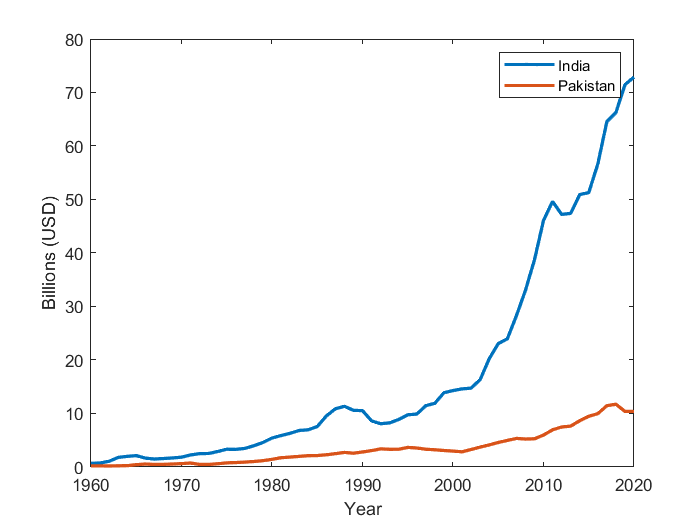

%plot data to help visualize trends

plot(timeline,india,'LineWidth',2)
hold on
plot(timeline,paki,'LineWidth',2)
%title("Military Spending by Year")
xlabel("Year")
ylabel("Billions (USD)")
legend("India", "Pakistan")
hold off

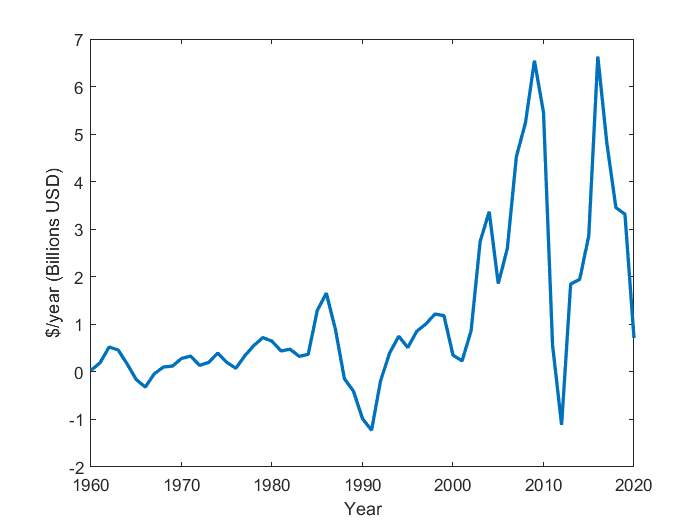


plot(timeline,indiaDer,'LineWidth',2)
%title("Change in India's Spending by Year")
xlabel("Year")
ylabel("$/year (Billions USD)")

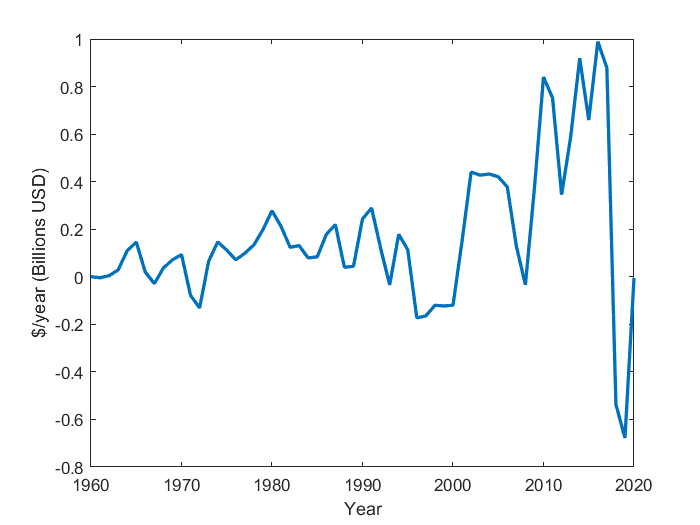


plot(timeline,pakiDer,'LineWidth',2)
%title("Change in Pakistan's Spending by Year")
xlabel("Year")
ylabel("$/year (Billions USD)")

%fit data to Richardson model
[india_fit, india_gof] = richardsonFit(india,paki,indiaDer);
[paki_fit, paki_gof] = richardsonFit(paki,india,pakiDer);

indiaParam = coeffvalues(india_fit); %extract parameters
indiaInt = confint(india_fit); %confidence intervals
dIdt = @(I,P) richardson(I,P,indiaParam(1),indiaParam(2),indiaParam(3)); %richardson model to describe India

pakiParam = coeffvalues(paki_fit); %extract parameters
pakiInt = confint(paki_fit); %confidence intervals
dPdt = @(P,I) richardson(P,I,pakiParam(1),pakiParam(2),pakiParam(3)); %richardson model to describe Pakistan

%system of linear equations defing the fitted Richardson model
f = @(t,X) [dIdt(X(1),X(2)); dPdt(X(2),X(1))];

%fixed point
[indiaFP, pakiFP] = richardsonFP(indiaParam(1),indiaParam(2),indiaParam(3),pakiParam(1),pakiParam(2),pakiParam(3));

%eigenvalues
[l1, l2] = richardsonEigen(indiaParam(1),indiaParam(2),pakiParam(1),pakiParam(2));

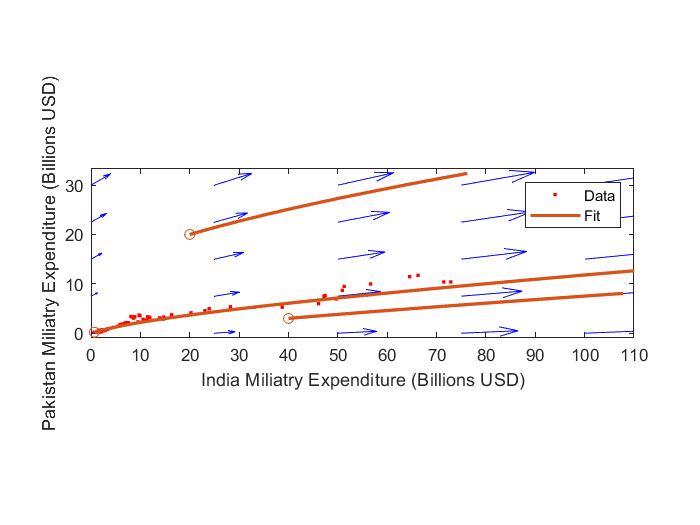

%plotting arrows
x1 = linspace(0,100,5);
y1 = linspace(0,30,5);

[x, y] = meshgrid(x1,y1);

u = zeros(size(x));
v = zeros(size(x));

t=0; 
for i = 1:numel(x)
    XPrime = f(t,[x(i); y(i)]); %find derivatives at these points
    u(i) = XPrime(1);
    v(i) = XPrime(2);
end

quiver(x,y,u,v,'b'); figure(gcf)
xlabel("India Miliatry Expenditure (Billions USD)")
ylabel("Pakistan Miliatry Expenditure (Billions USD)")
axis tight equal;
hold on

%plot data
%plot(india(1),paki(1),'r.','LineWidth',2) %starting point
%plot(india(end),paki(end),'gs','LineWidth',2) %ending point
d = plot(india,paki,'r.');
%plot(indiaFP,pakiFP,'ks','LineWidth',2)


%plotting various trajectories
[~,ys] = ode45(f,[0;60],[india(1),paki(1)]);
d2 = plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2);
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;17],[20;20]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;18],[40;3]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

%title("Richardson Model")
legend([d d2],"Data","Fit")
xlim([0 110])
hold off

%goodness of fit {'sse','rsquare','rmse'}

disp("India's Goodness of fit:" + newline + ...
    "* Sum of Squares due to Error " + num2str(india_gof.sse) + newline + ...
    "* R-Square " + num2str(india_gof.rsquare) + newline + ...
    "* Root Mean Square Error " + num2str(india_gof.rmse))

India's Goodness of fit:
* Sum of Squares due to Error 113.3386
* R-Square 0.40087
* Root Mean Square Error 1.3979


disp("Pakistan's Goodness of fit:" + newline + ...
    "* Sum of Squares due to Error " + num2str(paki_gof.sse) + newline + ...
    "* R-Square " + num2str(paki_gof.rsquare) + newline + ...
    "* Root Mean Square Error " + num2str(paki_gof.rmse))

Pakistan's Goodness of fit:
* Sum of Squares due to Error 4.9967
* R-Square 0.11133
* Root Mean Square Error 0.29351


%see parameters
disp("k = " + num2str(indiaParam(1)) + " within 95% confidence of " + num2str(indiaInt(:,1)') + newline + ...
    "a = " + num2str(indiaParam(2)) + " within 95% confidence of " + num2str(indiaInt(:,2)') + newline + ...
    "g = " + num2str(indiaParam(3)) + " within 95% confidence of " + num2str(indiaInt(:,3)') + newline + ...
    "k' = " + num2str(pakiParam(1)) + " within 95% confidence of " + num2str(pakiInt(:,1)') + newline + ...
    "a' = " + num2str(pakiParam(2)) + " within 95% confidence of " + num2str(pakiInt(:,2)') + newline + ...
    "g' = " + num2str(pakiParam(3))+ " within 95% confidence of " + num2str(pakiInt(:,3)'))

k = 0.03809 within 95% confidence of -0.4534     0.52958
a = -0.049317 within 95% confidence of -0.12473    0.026095
g = 0.18102 within 95% confidence of -0.42586      0.7879
k' = 0.0014143 within 95% confidence of -0.01442    0.017248
a' = -0.023544 within 95% confidence of -0.12674    0.079654
g' = 0.061436 within 95% confidence of -0.065988     0.18886


%fixed point and eigenvalue
disp("Fixed point at (x,y) = (" + num2str([indiaFP,pakiFP]) + ")" + newline + ...
    "Eigenvalue 1 = " + num2str(l1) + newline + ...
    "Eigenvalue 2 = " + num2str(l2))

Fixed point at (x,y) = (-1.7357     -2.5052)
Eigenvalue 1 = 0.05126
Eigenvalue 2 = 0.0216


### Military Spending (Smoothed)

We can try to improve the fit by smoothing the data with a rolling average.

indiaAve = movmean(india,5);
indiaAveDer = derivative(indiaAve,1,2);

pakiAve = movmean(paki,5);
pakiAveDer = derivative(pakiAve,1,2);

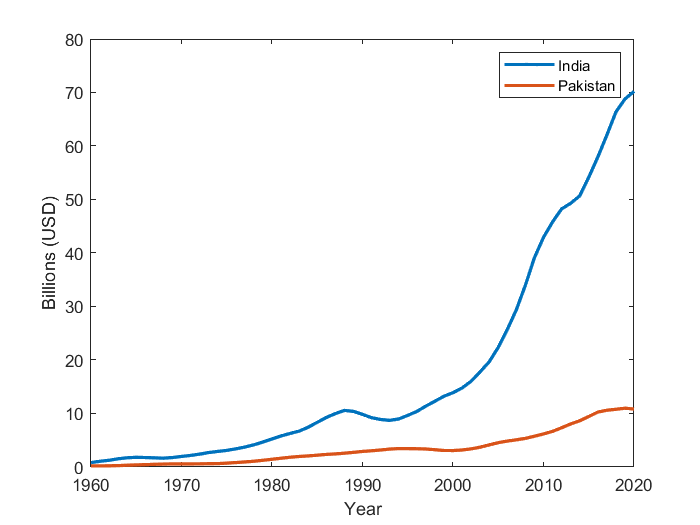

%plot data to help visualize trends

plot(timeline,indiaAve,'LineWidth',2)
hold on
plot(timeline,pakiAve,'LineWidth',2)
%title("Military Spending by Year")
xlabel("Year")
ylabel("Billions (USD)")
legend("India", "Pakistan")
hold off

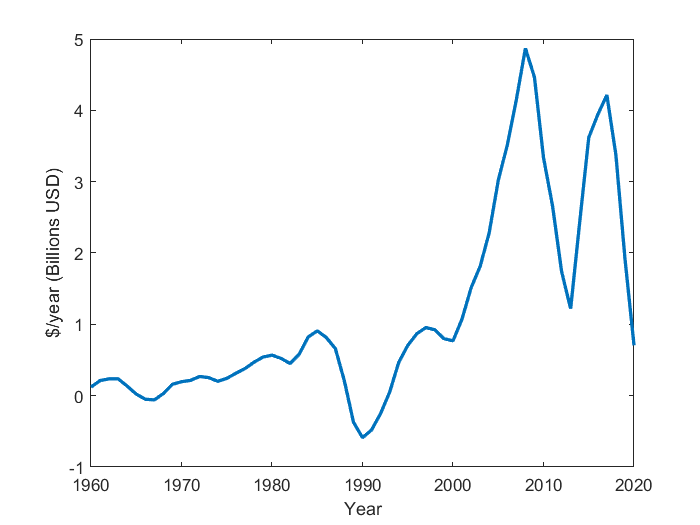


plot(timeline,indiaAveDer,'LineWidth',2)
%title("Change in India's Spending by Year")
xlabel("Year")
ylabel("$/year (Billions USD)")

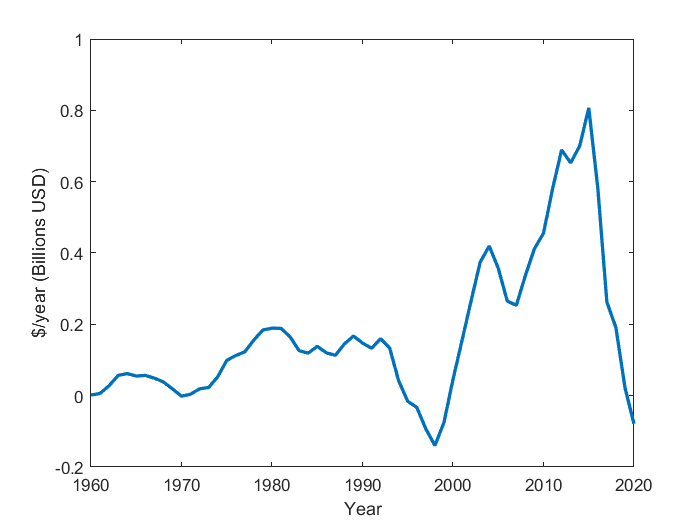


plot(timeline,pakiAveDer,'LineWidth',2)
%title("Change in Pakistan's Spending by Year")
xlabel("Year")
ylabel("$/year (Billions USD)")

%fit data to Richardson model
[indiaAve_fit, indiaAve_gof] = richardsonFit(indiaAve,pakiAve,indiaAveDer);
[pakiAve_fit, pakiAve_gof] = richardsonFit(pakiAve,indiaAve,pakiAveDer);

indiaAveParam = coeffvalues(indiaAve_fit); %extract parameters
indiaAveInt = confint(indiaAve_fit); %confidence intervals
dIdt = @(I,P) richardson(I,P,indiaAveParam(1),indiaAveParam(2),indiaAveParam(3));

pakiAveParam = coeffvalues(pakiAve_fit); %extract parameters
pakiAveInt = confint(pakiAve_fit); %confidence intervals
dPdt = @(P,I) richardson(P,I,pakiAveParam(1),pakiAveParam(2),pakiAveParam(3));

%system of linear equations defing the fitted Richardson model
f = @(t,X) [dIdt(X(1),X(2)); dPdt(X(2),X(1))];

%fixed point
[indiaAveFP, pakiAveFP] = richardsonFP(indiaAveParam(1),indiaAveParam(2),indiaAveParam(3),pakiAveParam(1),pakiAveParam(2),pakiAveParam(3));

%eigenvalues
[l1, l2] = richardsonEigen(indiaAveParam(1),indiaAveParam(2),pakiAveParam(1),pakiAveParam(2));

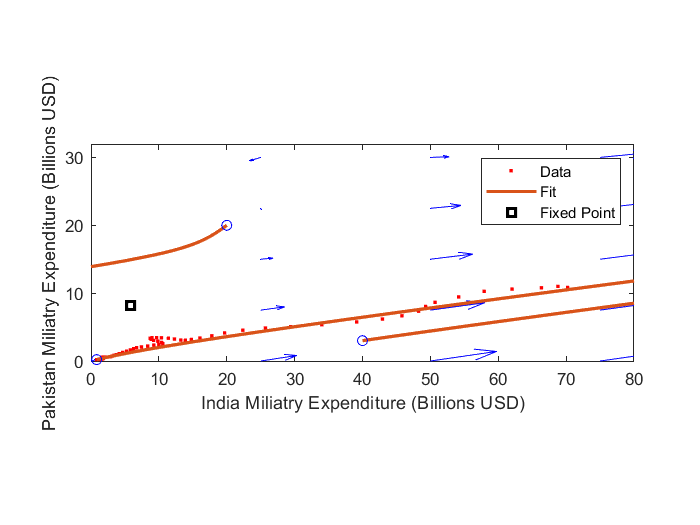

%plotting arrows
x1 = linspace(0,100,5);
y1 = linspace(0,30,5);

[x, y] = meshgrid(x1,y1);

u = zeros(size(x));
v = zeros(size(x));

t=0; 
for i = 1:numel(x)
    XPrime = f(t,[x(i); y(i)]); %find derivatives at these points
    u(i) = XPrime(1);
    v(i) = XPrime(2);
end

quiver(x,y,u,v,'b'); figure(gcf)
xlabel("India Miliatry Expenditure (Billions USD)")
ylabel("Pakistan Miliatry Expenditure (Billions USD)")
axis tight equal;
hold on

%plot data
%plot(indiaAve(1),pakiAve(1),'r.','LineWidth',2) %starting point
%plot(indiaAve(end),pakiAve(end),'gs','LineWidth',2) %ending point
d = plot(indiaAve,pakiAve,'r.');
fp = plot(indiaAveFP,pakiAveFP,'ks','LineWidth',2);

%plot nullclines


%plotting various trajectories
[~,ys] = ode45(f,[0;55],[indiaAve(1),pakiAve(1)]);
d2 = plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2);
plot(ys(1,1),ys(1,2),'bo') % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;85],[20;20]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'bo') % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;18],[40;3]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'bo') % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point


%title("Richardson Model (Smoothed)")
legend([d d2 fp],"Data","Fit","Fixed Point")
xlim([0 80])
hold off

%goodness of fit {'sse','rsquare','rmse'}

disp("India's Goodness of fit:" + newline + ...
    "* Sum of Squares due to Error " + num2str(indiaAve_gof.sse) + newline + ...
    "* R-Square " + num2str(indiaAve_gof.rsquare) + newline + ...
    "* Root Mean Square Error " + num2str(indiaAve_gof.rmse))

India's Goodness of fit:
* Sum of Squares due to Error 53.3456
* R-Square 0.54146
* Root Mean Square Error 0.95904



disp("Pakistan's Goodness of fit:" + newline + ...
    "* Sum of Squares due to Error " + num2str(pakiAve_gof.sse) + newline + ...
    "* R-Square " + num2str(pakiAve_gof.rsquare) + newline + ...
    "* Root Mean Square Error " + num2str(pakiAve_gof.rmse))

Pakistan's Goodness of fit:
* Sum of Squares due to Error 1.6776
* R-Square 0.35635
* Root Mean Square Error 0.17007



%see parameters
disp("k = " + num2str(indiaAveParam(1)) + " within 95% confidence of " + num2str(indiaAveInt(:,1)') + newline + ...
    "a = " + num2str(indiaAveParam(2)) + " within 95% confidence of " + num2str(indiaAveInt(:,2)') + newline + ...
    "g = " + num2str(indiaAveParam(3)) + " within 95% confidence of " + num2str(indiaAveInt(:,3)') + newline + ...
    "k' = " + num2str(pakiAveParam(1)) + " within 95% confidence of " + num2str(pakiAveInt(:,1)') + newline + ...
    "a' = " + num2str(pakiAveParam(2)) + " within 95% confidence of " + num2str(pakiAveInt(:,2)') + newline + ...
    "g' = " + num2str(pakiAveParam(3)) + " within 95% confidence of " + num2str(pakiAveInt(:,3)'))

k = -0.082655 within 95% confidence of -0.49222     0.32691
a = -0.063295 within 95% confidence of -0.12656  -2.767e-05
g = 0.30047 within 95% confidence of -0.14436      0.7453
k' = 0.00852 within 95% confidence of -0.0026997     0.01974
a' = 0.01561 within 95% confidence of -0.05702    0.088241
g' = 0.076857 within 95% confidence of -0.0020278     0.15574


%fixed point and eigenvalue
disp("Fixed point at (x,y) = (" + num2str([indiaAveFP,pakiAveFP]) + ")" + newline + ...
    "Eigenvalue 1 = " + num2str(l1) + newline + ...
    "Eigenvalue 2 = " + num2str(l2))

Fixed point at (x,y) = (5.8561      8.1197)
Eigenvalue 1 = 0.053037
Eigenvalue 2 = -0.0053517


### Percent Spending

Analyze India's and Pakistan's military spending as a percent of GDP.

%extract data for India and find the derivatives of the list 
indiaIdx = percentFull.CountryName == 'India';
indiaPer = percentFull{indiaIdx, vartype('numeric')};
indiaPerDer = derivative(indiaPer,1,2);

%extract data for Pakistan and find the derivatives of the list 
pakiIdx = percentFull.CountryName == 'Pakistan';
pakiPer = percentFull{pakiIdx, vartype('numeric')};
pakiPerDer = derivative(pakiPer,1,2);

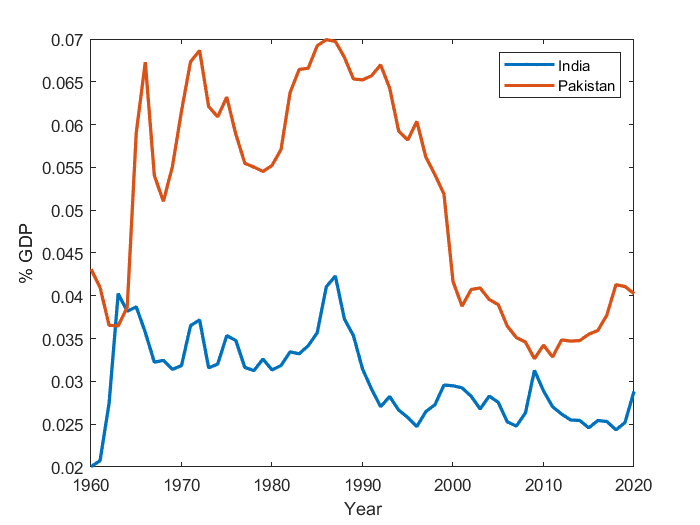

%plot data to help visualize trends

plot(timeline,indiaPer,'LineWidth',2)
hold on
plot(timeline,pakiPer,'LineWidth',2)
%title("Military Spending by Year")
xlabel("Year")
ylabel("% GDP")
legend("India", "Pakistan")
hold off

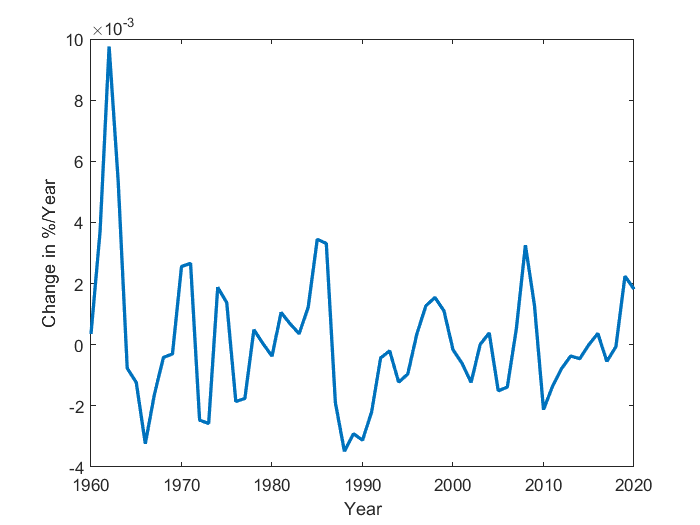


plot(timeline,indiaPerDer,'LineWidth',2)
%title("Change in India's Spending by Year")
xlabel("Year")
ylabel("Change in %/Year")

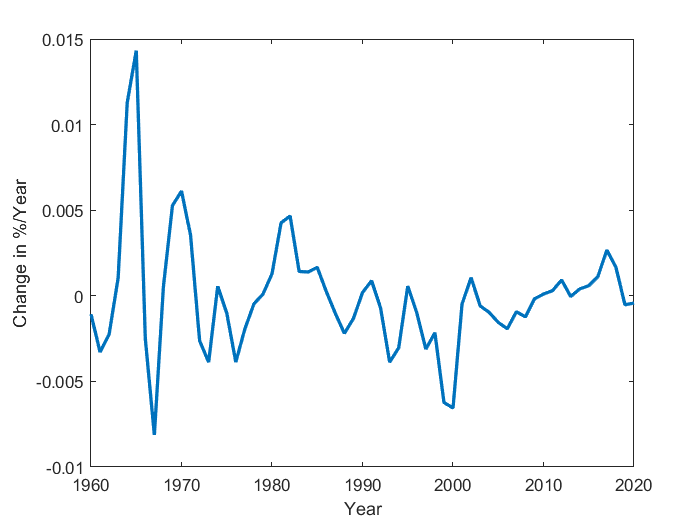


plot(timeline,pakiPerDer,'LineWidth',2)
%title("Change in Pakistan's Spending by Year")
xlabel("Year")
ylabel("Change in %/Year")

%fit data to Richardson model
[indiaPer_fit, indiaPer_gof] = richardsonFit(indiaPer,pakiPer,indiaPerDer);
[pakiPer_fit, pakiPer_gof] = richardsonFit(pakiPer,indiaPer,pakiPerDer);

indiaPerParam = coeffvalues(indiaPer_fit); %extract parameters
indiaPerInt = confint(indiaPer_fit); %confidence intervals
dIdt = @(I,P) richardson(I,P,indiaPerParam(1),indiaPerParam(2),indiaPerParam(3));

pakiPerParam = coeffvalues(pakiPer_fit); %extract parameters
pakiPerInt = confint(pakiPer_fit); %confidence intervals
dPdt = @(P,I) richardson(P,I,pakiPerParam(1),pakiPerParam(2),pakiPerParam(3));

%system of linear equations defing the fitted Richardson model
f = @(t,X) [dIdt(X(1),X(2)); dPdt(X(2),X(1))];

%fixed point
[indiaPerFP, pakiPerFP] = richardsonFP(indiaPerParam(1),indiaPerParam(2),indiaPerParam(3),pakiPerParam(1),pakiPerParam(2),pakiPerParam(3));

%eigenvalues
[l1, l2] = richardsonEigen(indiaPerParam(1),indiaPerParam(2),pakiPerParam(1),pakiPerParam(2));

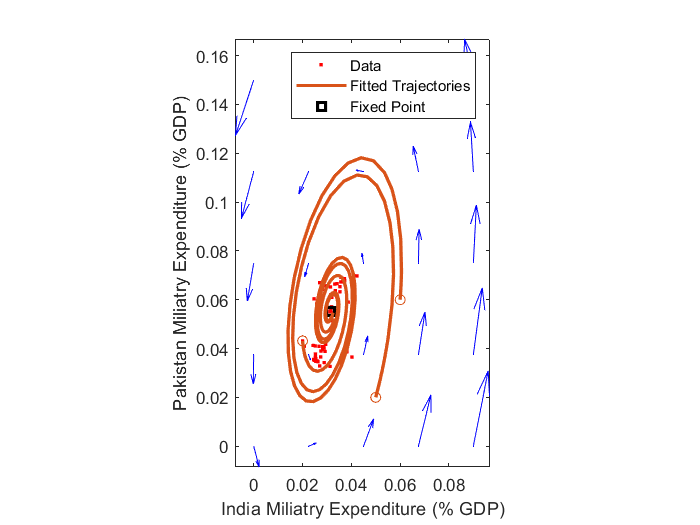

%plotting arrows
x1 = linspace(0,0.09,5);
y1 = linspace(0,0.15,5);

[x, y] = meshgrid(x1,y1);

u = zeros(size(x));
v = zeros(size(x));

t=0; 
for i = 1:numel(x)
    XPrime = f(t,[x(i); y(i)]); %find derivatives at these points
    u(i) = XPrime(1);
    v(i) = XPrime(2);
end

quiver(x,y,u,v,'b'); figure(gcf)
xlabel("India Miliatry Expenditure (% GDP)")
ylabel("Pakistan Miliatry Expenditure (% GDP)")
axis tight equal;
hold on

%plot data
%plot(indiaPer(1),pakiPer(1),'r.','LineWidth',2) %starting point
%plot(indiaPer(end),pakiPer(end),'gs','LineWidth',2) %ending point
d = plot(indiaPer,pakiPer,'r.');
fp = plot(indiaPerFP,pakiPerFP,'ks','LineWidth',2);

%plotting various trajectories
[~,ys] = ode45(f,[0;85],[indiaPer(1),pakiPer(1)]);
d2 = plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2);
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;185],[0.06;0.06]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;185],[0.05,0.02]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

%title("Richardson Model (Smoothed)")
legend([d d2 fp],"Data","Fitted Trajectories","Fixed Point")
hold off

%goodness of fit {'sse','rsquare','rmse'}

disp("India's Goodness of fit:" + newline + ...
    "* Sum of Squares due to Error " + num2str(indiaPer_gof.sse) + newline + ...
    "* R-Square " + num2str(indiaPer_gof.rsquare) + newline + ...
    "* Root Mean Square Error " + num2str(indiaPer_gof.rmse))

India's Goodness of fit:
* Sum of Squares due to Error 0.00028529
* R-Square 0.044666
* Root Mean Square Error 0.0022178


disp("Pakistan's Goodness of fit:" + newline + ...
    "* Sum of Squares due to Error " + num2str(pakiPer_gof.sse) + newline + ...
    "* R-Square " + num2str(pakiPer_gof.rsquare) + newline + ...
    "* Root Mean Square Error " + num2str(pakiPer_gof.rmse))

Pakistan's Goodness of fit:
* Sum of Squares due to Error 0.0006669
* R-Square 0.10628
* Root Mean Square Error 0.0033909


%see parameters
disp("k = " + num2str(indiaPerParam(1)) + " within 95% confidence of " + num2str(indiaPerInt(:,1)') + newline + ...
    "a = " + num2str(indiaPerParam(2)) + " within 95% confidence of " + num2str(indiaPerInt(:,2)') + newline + ...
    "g = " + num2str(indiaPerParam(3)) + " within 95% confidence of " + num2str(indiaPerInt(:,3)') + newline + ...
    "k' = " + num2str(pakiPerParam(1)) + " within 95% confidence of " + num2str(pakiPerInt(:,1)') + newline + ...
    "a' = " + num2str(pakiPerParam(2)) + " within 95% confidence of " + num2str(pakiPerInt(:,2)') + newline + ...
    "g' = " + num2str(pakiPerParam(3))+ " within 95% confidence of " + num2str(pakiPerInt(:,3)'))

k = -0.042227 within 95% confidence of -0.097477    0.013023
a = -0.027865 within 95% confidence of -0.17075     0.11502
g = 0.001464 within 95% confidence of -0.0021236   0.0050515
k' = 0.28648 within 95% confidence of 0.068018     0.50495
a' = 0.061378 within 95% confidence of -0.023095     0.14585
g' = -0.0055811 within 95% confidence of -0.011066 -9.5896e-05


%fixed point and eigenvalue
disp("Fixed point at (x,y) = (" + num2str([indiaPerFP,pakiPerFP]) + ")" + newline + ...
    "Eigenvalue 1 = " + num2str(l1) + newline + ...
    "Eigenvalue 2 = " + num2str(l2))

Fixed point at (x,y) = (0.03134     0.05535)
Eigenvalue 1 = -0.016757+0.10053i
Eigenvalue 2 = -0.016757-0.10053i


### Percent Spending (Smoothed)

indiaPerAve = movmean(indiaPer,5);
indiaPerAveDer = derivative(indiaPerAve,1,2);

pakiPerAve = movmean(pakiPer,5);
pakiPerAveDer = derivative(pakiPerAve,1,2);

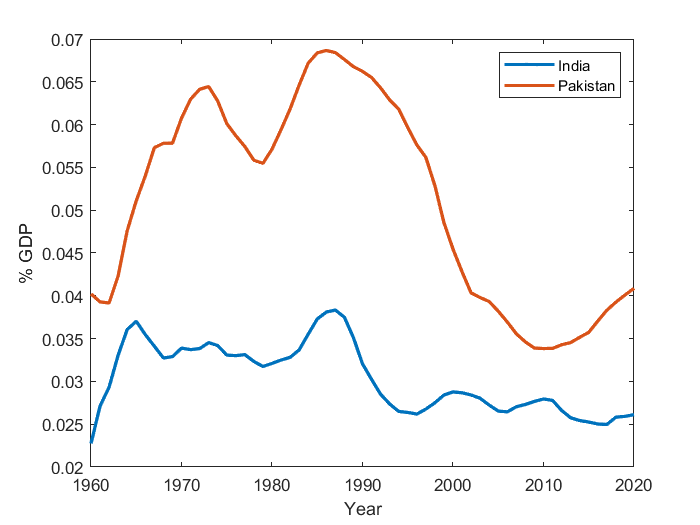

%plot data to help visualize trends

plot(timeline,indiaPerAve,'LineWidth',2)
hold on
plot(timeline,pakiPerAve,'LineWidth',2)
%title("Military Spending by Year")
xlabel("Year")
ylabel("% GDP")
legend("India", "Pakistan")
hold off

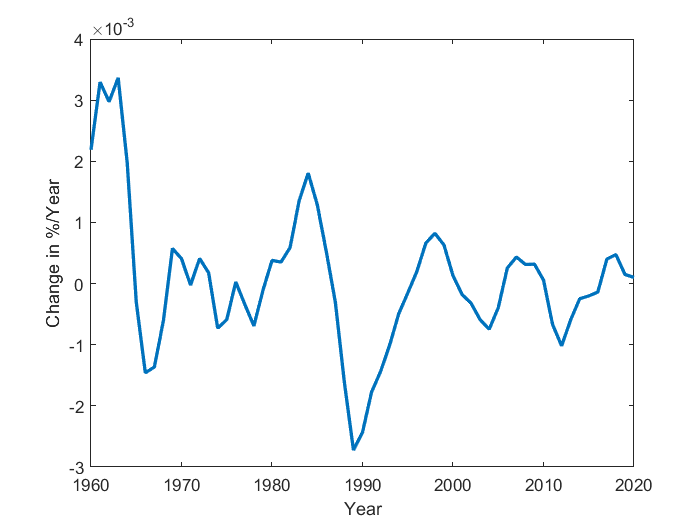


plot(timeline,indiaPerAveDer,'LineWidth',2)
%title("Change in India's Spending by Year")
xlabel("Year")
ylabel("Change in %/Year")

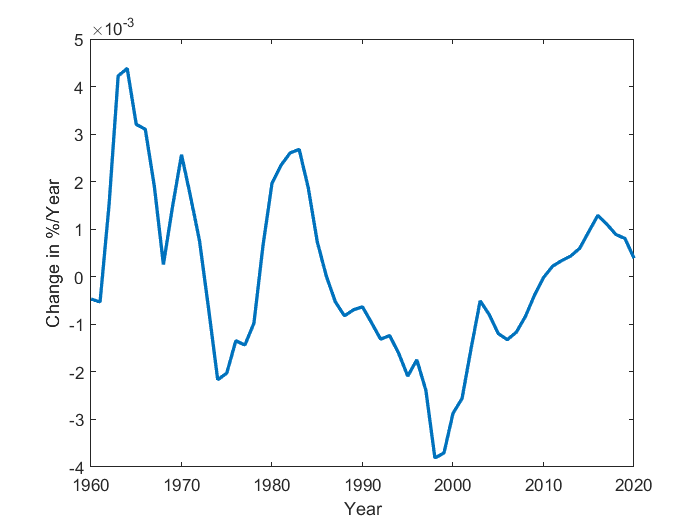


plot(timeline,pakiPerAveDer,'LineWidth',2)
%title("Change in Pakistan's Spending by Year")
xlabel("Year")
ylabel("Change in %/Year")

%fit data to Richardson model
[indiaPerAve_fit, indiaPerAve_gof] = richardsonFit(indiaPerAve,pakiPerAve,indiaPerAveDer);
[pakiPerAve_fit, pakiPerAve_gof] = richardsonFit(pakiPerAve,indiaPerAve,pakiPerAveDer);

indiaPerAveParam = coeffvalues(indiaPerAve_fit); %extract parameters
indiaPerAveInt = confint(indiaPerAve_fit); %confidence intervals
dIdt = @(I,P) richardson(I,P,indiaPerAveParam(1),indiaPerAveParam(2),indiaPerAveParam(3));

pakiPerAveParam = coeffvalues(pakiPerAve_fit); %extract parameters
pakiPerAveInt = confint(pakiPerAve_fit); %confidence intervals
dPdt = @(P,I) richardson(P,I,pakiPerAveParam(1),pakiPerAveParam(2),pakiPerAveParam(3));

%system of linear equations defing the fitted Richardson model
f = @(t,X) [dIdt(X(1),X(2)); dPdt(X(2),X(1))];

%fixed point
[indiaPerAveFP, pakiPerAveFP] = richardsonFP(indiaPerAveParam(1),indiaPerAveParam(2),indiaPerAveParam(3),pakiPerAveParam(1),pakiPerAveParam(2),pakiPerAveParam(3));

%eigenvalues
[l1, l2] = richardsonEigen(indiaPerAveParam(1),indiaPerAveParam(2),pakiPerAveParam(1),pakiPerAveParam(2));

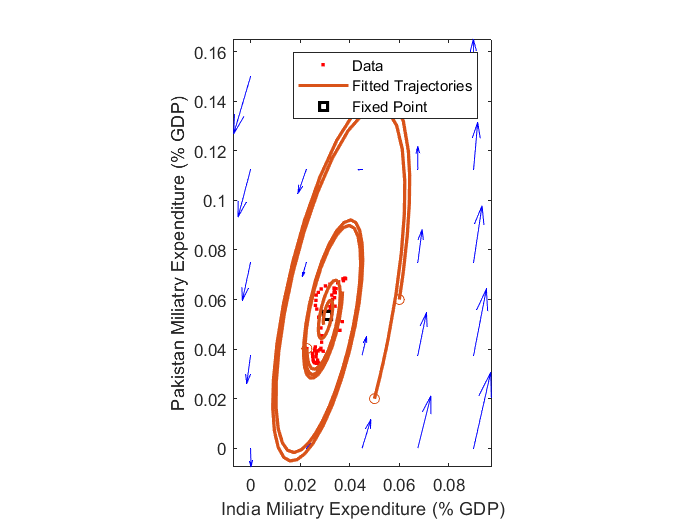

%plotting arrows
x1 = linspace(0,0.09,5);
y1 = linspace(0,0.15,5);

[x, y] = meshgrid(x1,y1);

u = zeros(size(x));
v = zeros(size(x));

t=0; 
for i = 1:numel(x)
    XPrime = f(t,[x(i); y(i)]);
    u(i) = XPrime(1);
    v(i) = XPrime(2);
end

quiver(x,y,u,v,'b'); figure(gcf)
xlabel("India Miliatry Expenditure (% GDP)")
ylabel("Pakistan Miliatry Expenditure (% GDP)")
axis tight equal;
hold on

%plot data
%plot(indiaPerAve(1),pakiPerAve(1),'r.','LineWidth',2) %starting point
%plot(indiaPerAve(end),pakiPerAve(end),'gs','LineWidth',2) %ending point
d = plot(indiaPerAve,pakiPerAve,'r.');
fp = plot(indiaPerAveFP,pakiPerAveFP,'ks','LineWidth',2);

%plotting various trajectories
[~,ys] = ode45(f,[0;150],[indiaPerAve(1),pakiPerAve(1)]);
d2 = plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2);
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;150],[0.06;0.06]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;150],[0.05,0.02]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'o','Color',[0.8500 0.3250 0.0980]) % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

%title("Richardson Model (% of GDP)")
legend([d d2 fp],"Data","Fitted Trajectories","Fixed Point")
hold off

%goodness of fit {'sse','rsquare','rmse'}

disp("India's Goodness of fit:" + newline + ...
    "* Sum of Squares due to Error " + num2str(indiaPerAve_gof.sse) + newline + ...
    "* R-Square " + num2str(indiaPerAve_gof.rsquare) + newline + ...
    "* Root Mean Square Error " + num2str(indiaPerAve_gof.rmse))

India's Goodness of fit:
* Sum of Squares due to Error 7.574e-05
* R-Square 0.075908
* Root Mean Square Error 0.0011427


disp("Pakistan's Goodness of fit:" + newline + ...
    "* Sum of Squares due to Error " + num2str(pakiPerAve_gof.sse) + newline + ...
    "* R-Square " + num2str(pakiPerAve_gof.rsquare) + newline + ...
    "* Root Mean Square Error " + num2str(pakiPerAve_gof.rmse))

Pakistan's Goodness of fit:
* Sum of Squares due to Error 0.00014248
* R-Square 0.27626
* Root Mean Square Error 0.0015673


%see parameters
disp("k = " + num2str(indiaPerAveParam(1)) + " within 95% confidence of " + num2str(indiaPerAveInt(:,1)') + newline + ...
    "a = " + num2str(indiaPerAveParam(2)) + " within 95% confidence of " + num2str(indiaPerAveInt(:,2)') + newline + ...
    "g = " + num2str(indiaPerAveParam(3)) + " within 95% confidence of " + num2str(indiaPerAveInt(:,3)') + newline + ...
    "k' = " + num2str(pakiPerAveParam(1)) + " within 95% confidence of " + num2str(pakiPerAveInt(:,1)') + newline + ...
    "a' = " + num2str(pakiPerAveParam(2)) + " within 95% confidence of " + num2str(pakiPerAveInt(:,2)') + newline + ...
    "g' = " + num2str(pakiPerAveParam(3))+ " within 95% confidence of " + num2str(pakiPerAveInt(:,3)'))

k = -0.037242 within 95% confidence of -0.072553  -0.0019303
a = -0.059469 within 95% confidence of -0.16451    0.045571
g = 0.00015997 within 95% confidence of -0.0021234   0.0024433
k' = 0.33863 within 95% confidence of 0.19456     0.48269
a' = 0.082682 within 95% confidence of 0.034251     0.13111
g' = -0.0060209 within 95% confidence of -0.0091526  -0.0028893


%fixed point and eigenvalue
disp("Fixed point at (x,y) = (" + num2str([indiaPerAveFP,pakiPerAveFP]) + ")" + newline + ...
    "Eigenvalue 1 = " + num2str(l1) + newline + ...
    "Eigenvalue 2 = " + num2str(l2))

Fixed point at (x,y) = (0.030862    0.053578)
Eigenvalue 1 = -0.011606+0.086945i
Eigenvalue 2 = -0.011606-0.086945i


### Nuclear Arms Race

dataLines = [2, Inf];
filename = "number-of-nuclear-warheads-in-the-inventory-of-the-nuclear-powers.csv";
%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 4);

% Specify range and delimiter
opts.DataLines = dataLines;
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Entity", "Code", "Year", "Count"];
opts.VariableTypes = ["categorical", "categorical", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Entity", "Code"], "EmptyFieldRule", "auto");

% Import the data
nukeRaw = readtable(filename, opts);

clear opts filename datalines

timelineNuke = 1998:2017;

%Pakistan's nukes
pakiIdx = nukeRaw.Entity == 'Pakistan' & nukeRaw.Year>=1998;
pakiNuke = nukeRaw.Count(pakiIdx);

%India's nukes during the cold war
indiaIdx = nukeRaw.Entity == 'India' & nukeRaw.Year>=1998;
indiaNuke = nukeRaw.Count(indiaIdx);

%change in nuclear stockpile with time
indiaNukeDer = derivative(indiaNuke,1,1);

pakiNukeDer = derivative(pakiNuke,1,1);

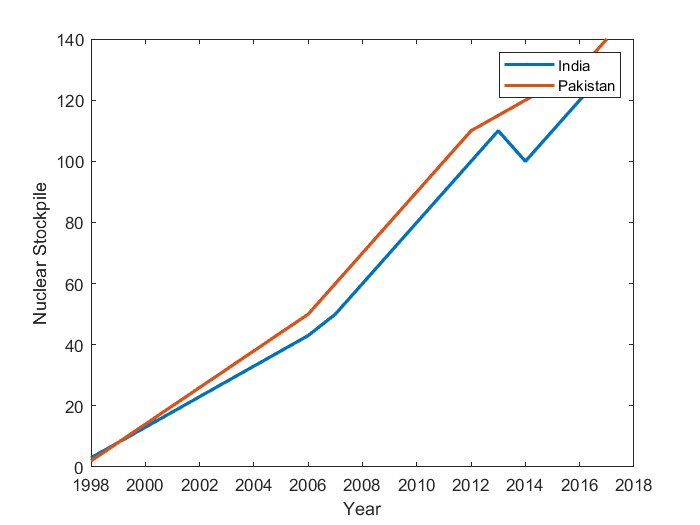

plot(timelineNuke,indiaNuke,"LineWidth",2);
hold on
plot(timelineNuke,pakiNuke,"LineWidth",2)
legend("India","Pakistan")
xlabel("Year")
ylabel("Nuclear Stockpile")
ylim([0 140])
hold off

%fit data to Richardson model
[indiaNuke_fit, indiaNuke_gof] = richardsonFit(indiaNuke,pakiNuke,indiaNukeDer);
[pakiNuke_fit, pakiNuke_gof] = richardsonFit(pakiNuke,indiaNuke,pakiNukeDer);

indiaNukeParam = coeffvalues(indiaNuke_fit); %extract parameters
indiaNukeInt = confint(indiaNuke_fit); %confidence intervals
dINdt = @(I,P) richardson(I,P,indiaNukeParam(1),indiaNukeParam(2),indiaNukeParam(3));

pakiNukeParam = coeffvalues(pakiNuke_fit); %extract parameters
pakiNukeInt = confint(pakiNuke_fit); %confidence intervals
dPNdt = @(P,I) richardson(P,I,pakiNukeParam(1),pakiNukeParam(2),pakiNukeParam(3));

%system of linear equations defing the fitted Richardson model
f = @(t,X) [dINdt(X(1),X(2)); dPNdt(X(2),X(1))];

%fixed point and eigenvalues
[indiaNukeFP,pakiNukeFP] = richardsonFP(indiaNukeParam(1),indiaNukeParam(2),indiaNukeParam(3),pakiNukeParam(1),pakiNukeParam(2),pakiNukeParam(3));
[l1, l2] = richardsonEigen(indiaNukeParam(1),indiaNukeParam(2),pakiNukeParam(1),pakiNukeParam(2));

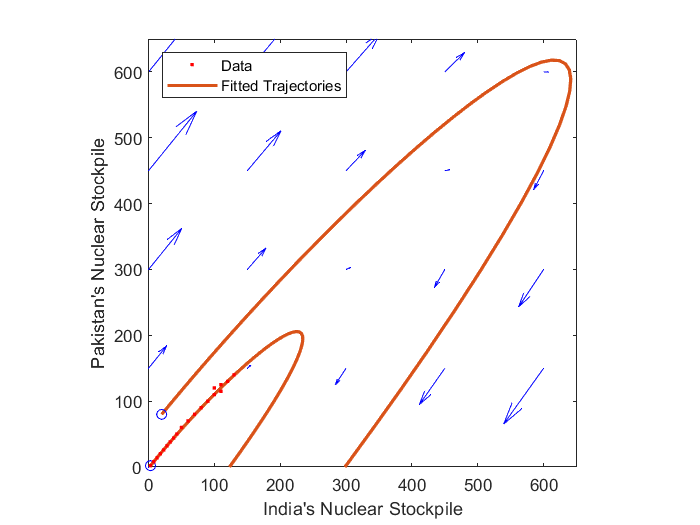

%plotting arrows
x1 = linspace(0,600,5);
y1 = linspace(0,600,5);

[x, y] = meshgrid(x1,y1);

u = zeros(size(x));
v = zeros(size(x));

t=0; 
for i = 1:numel(x)
    XPrime = f(t,[x(i); y(i)]);
    u(i) = XPrime(1);
    v(i) = XPrime(2);
end

quiver(x,y,u,v,'b'); figure(gcf)
xlabel("India's Nuclear Stockpile")
ylabel("Pakistan's Nuclear Stockpile")
axis tight equal;
hold on

%plotting various trajectories
[~,ys] = ode45(f,[0;63],[indiaNuke(1),pakiNuke(1)]); %63 years from 1998
d2 = plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2);
plot(ys(1,1),ys(1,2),'bo') % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

%[~,ys] = ode45(f,[0;20],[110,80]);
%plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
%plot(ys(1,1),ys(1,2),'bo') % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

[~,ys] = ode45(f,[0;60],[20,80]);
plot(ys(:,1),ys(:,2),'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot(ys(1,1),ys(1,2),'bo') % starting point
%plot(ys(end,1),ys(end,2),'ks') % ending point

%plot data
%plot(indiaNuke(1),pakiNuke(1),'r.','LineWidth',2) %starting point
%plot(indiaNuke(end),pakiNuke(end),'gs','LineWidth',2) %ending point
d = plot(indiaNuke,pakiNuke,'r.');
%fp = plot(indiaNukeFP,pakiNukeFP,'ks','LineWidth',2);

%title("Richardson Model (Nuclear Weapons)")
legend([d d2],"Data","Fitted Trajectories",'Location','northwest')
xlim([0 650])
ylim([0 650])
hold off

%goodness of fit {'sse','rsquare','rmse'}

disp("India's Goodness of fit:" + newline + ...
    "* Sum of Squares due to Error " + num2str(indiaNuke_gof.sse) + newline + ...
    "* R-Square " + num2str(indiaNuke_gof.rsquare) + newline + ...
    "* Root Mean Square Error " + num2str(indiaNuke_gof.rmse))

India's Goodness of fit:
* Sum of Squares due to Error 189.603
* R-Square 0.088666
* Root Mean Square Error 3.3396



disp("Pakistan's Goodness of fit:" + newline + ...
    "* Sum of Squares due to Error " + num2str(pakiNuke_gof.sse) + newline + ...
    "* R-Square " + num2str(pakiNuke_gof.rsquare) + newline + ...
    "* Root Mean Square Error " + num2str(pakiNuke_gof.rmse))

Pakistan's Goodness of fit:
* Sum of Squares due to Error 75.598
* R-Square 0.11374
* Root Mean Square Error 2.1088


%see parameters
disp("k = " + num2str(indiaNukeParam(1)) + " within 95% confidence of " + num2str(indiaNukeInt(:,1)') + newline + ...
    "a = " + num2str(indiaNukeParam(2)) + " within 95% confidence of " + num2str(indiaNukeInt(:,2)') + newline + ...
    "g = " + num2str(indiaNukeParam(3)) + " within 95% confidence of " + num2str(indiaNukeInt(:,3)') + newline + ...
    "k' = " + num2str(pakiNukeParam(1)) + " within 95% confidence of " + num2str(pakiNukeInt(:,1)') + newline + ...
    "a' = " + num2str(pakiNukeParam(2)) + " within 95% confidence of " + num2str(pakiNukeInt(:,2)') + newline + ...
    "g' = " + num2str(pakiNukeParam(3)) + " within 95% confidence of " + num2str(pakiNukeInt(:,3)'))

k = 0.15557 within 95% confidence of -0.33112     0.64225
a = 0.15021 within 95% confidence of -0.38514     0.68555
g = 4.8778 within 95% confidence of 1.9134      7.8423
k' = -0.20244 within 95% confidence of -0.54048      0.1356
a' = -0.19174 within 95% confidence of -0.49905     0.11558
g' = 6.1471 within 95% confidence of 4.2752      8.0189


%fixed point and eigenvalue
disp("Fixed point at (x,y) = (" + num2str([indiaNukeFP,pakiNukeFP]) + ")" + newline + ...
    "Eigenvalue 1 = " + num2str(l1) + newline + ...
    "Eigenvalue 2 = " + num2str(l2))

Fixed point at (x,y) = (7.80457     -23.8198)
Eigenvalue 1 = 0.020765+0.047545i
Eigenvalue 2 = 0.020765-0.047545i


## Useful Functions

function dx = derivative(X,t,dim)
  % X (vector or 2D array), t (scalar), dim (scalar)
  %
  % Computes the numerical derivatives from a list of data points, X, with
  % a time step, t, using the secant method.
  %   dx/dt = (f(X(i+1))-f(X(i-1)))/2t
  %
  % End cases are special:
  %   dx (first) = (second entry - current entry)/2t
  %   dx (end) = (last entry - second to last entry)/2t
  %
  % Error of t^2
  
  if dim==1
    dx = zeros(size(X));
      
    dx(1,:) = (X(2,:)-X(1,:))/(2*t);
    dx(end,:) = (X(end,:)-X(end-1,:))/(2*t);
    for i=2:size(X,1)-1
      dx(i,:) = (X(i+1,:)-X(i-1,:))/(2*t);
    end
  elseif dim==2
    dx = zeros(size(X));
    
    dx(:,1) = (X(:,2)-X(:,1))/(2*t);
    dx(:,end) = (X(:,end)-X(:,end-1))/(2*t);
    for i=2:size(X,2)-1
      dx(:,i) = (X(:,i+1)-X(:,i-1))/(2*t);
    end
  else
    error("The \'dim\' argument must be 1 or 2, X must be a vector or a 2D array.")
  end
end

function [x,y] = richardsonFP(k,a,g,kp,ap,gp)
  % All inputs are scalars
  % 
  % Calculates the fixed point of the Richardson model with the given parameters
  
  x = (gp*k+g*ap)/(a*ap-k*kp);
  y = (g*kp+gp*a)/(a*ap-k*kp);
end

function [lambda1,lambda2] = richardsonEigen(k,a,kp,ap)
  % All inputs are scalars
  % 
  % Calculates the eignevalues of the fixed point of the Richardson model with the given parameters
  
  tr = -a-ap; %trace
  d = a*ap-k*kp; %detemrinant 
  lambda1 = (tr+sqrt(tr^2-4*d))/2;
  lambda2 = (tr-sqrt(tr^2-4*d))/2;
end